Generating Graph

% clear previous variables
clear;


% %initial random graphs
% n=40; % nodes numbe
% e=1.1*n; % edges number
% G = graph(true(n), 'omitselfloops');
% p=randperm(numedges(G),e);
% G=graph(G.Edges(p,:));
% 
% %initial node positions
% nodePositions=randi(100,n,2);
% distance=nodePositions(:,1).^2+nodePositions(:,2).^2;
% [~,sortIndex]=sort(distance);
% nodePositions=nodePositions(sortIndex,sortIndex);
% 
% %plot graphs
% figure;
% plot(G,'XData', nodePositions(:,1), 'YData', nodePositions(:,2), 'NodeLabel', 1:n);
% hold on;
% 
% % Highlight the start node (assuming startNode is the ID of the start node)
% plot(nodePositions(1,1), nodePositions(1,2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
% 
% % Highlight the goal node (assuming goalNode is the ID of the goal node)
% plot(nodePositions(n,1), nodePositions(n,2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% 
% hold off;

%---- Initial graphs -------
%preset node positions
nodes_positions=[-0.5	-0.5
    -0.09	-0.4
    -0.285	-0.305
    0.0575	-0.225
    -0.0525	-0.0175
    -0.37	0.3
    0.3525	-0.0525
    0.0625	0.255
    -0.1	0.3725
    0.4275	0.195
    0.345	0.3525
    0.5	0.5
    ];

% preset edges and costs
edges=[12	11	0.214
12	10	0.3135
12	8	0.5014
11	10	0.1778
11	9	0.4454
10	7	0.2586
9	8	0.2005
9	6	0.2796
9	5	0.5994
8	4	0.48
5	2	0.179
4	3	0.3517
4	2	0.2289
3	2	0.2169
3	1	0.2903
2	1	0.422
7	5	0.4402
5	4	0.11
];

G=graph(edges(:,1),edges(:,2),edges(:,3)) %the Graph

G =   graph with properties:

    Edges: [18×2 table]
    Nodes: [12×0 table]


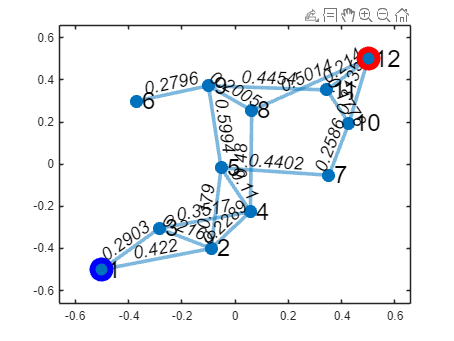

% suppossing starting node is 1, goal node is 12
star_node =1;
goal_node= 12;
%^^^^^^^^^^^ Initial graphs ^^^^^^^^

%-----------plot the graph------------
% plot the graph
plot(G,"XData",nodes_positions(:,1),"YData",nodes_positions(:,2),"LineWidth",3,"MarkerSize",10,"NodeFontSize",20,"EdgeLabel",G.Edges.Weight,"EdgeFontSize",15)

% mark start and goal nodes
hold on;
plot(nodes_positions(star_node,1),nodes_positions(star_node,2),'bo',"MarkerSize",15,"LineWidth",5);
plot(nodes_positions(goal_node,1),nodes_positions(goal_node,2),'ro',"MarkerSize",15,"LineWidth",5);

hold off;

%-^^^^^^^^^^plot the graph^^^^^^^^^^^^

Breadth First Search

neighbors(G,1)

ans =      2
     3
